# Part 1: Impact of the masks to images

% 1. Loaf all images
cam = imread("cameraman.tif");
lena = imread("Lena-1.tif");
race = imread("race.tif");
noise1 = imread("noise1.tif");
noise2 = imread("noise2.tif");
% 2. Filters using the provided matrix
a_filter = ones(3,3) / 9;
b_filter = [1 2 1; 2 4 2; 1 2 1] / 16;
c_filter = [0 1 0; 1 1 1; 0 1 0] / 5;
d_filter = ones(5,5) / 25;
% Initialising the matrix for filter e
matrix = ones(5, 5);
matrix([1, 1, 5, 5], [1, 5, 1, 5]) = 0;
e_filter = matrix / 25;

% 3. Apply filter on cameraman image
cam_a = imfilter(cam, a_filter, "replicate");
cam_b = imfilter(cam, b_filter, "replicate");
cam_c = imfilter(cam, c_filter, "replicate");
cam_d = imfilter(cam, d_filter, "replicate");
cam_e = imfilter(cam, e_filter, "replicate");
% 3. Apply filter on noise2 image
noise2_a = imfilter(noise2, a_filter, "replicate");
noise2_b = imfilter(noise2, b_filter, "replicate");
noise2_c = imfilter(noise2, c_filter, "replicate");
noise2_d = imfilter(noise2, d_filter, "replicate");
noise2_e = imfilter(noise2, e_filter, "replicate");

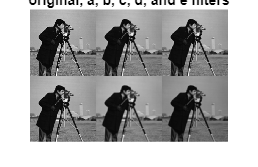

% Plot the cameraman image with filters applied
figure;
montage({cam, cam_a, cam_b, cam_c, cam_d, cam_e});
title("original, a, b, c, d, and e filters");

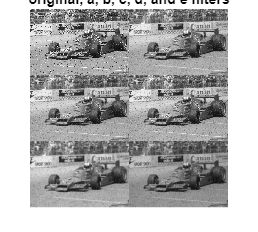

% Noise2 image with filter applied
figure;
montage({noise2, noise2_a, noise2_b, noise2_c, noise2_d, noise2_e});
title("original, a, b, c, d, and e filters");

## Part 2: Evaluation of Filters Performance

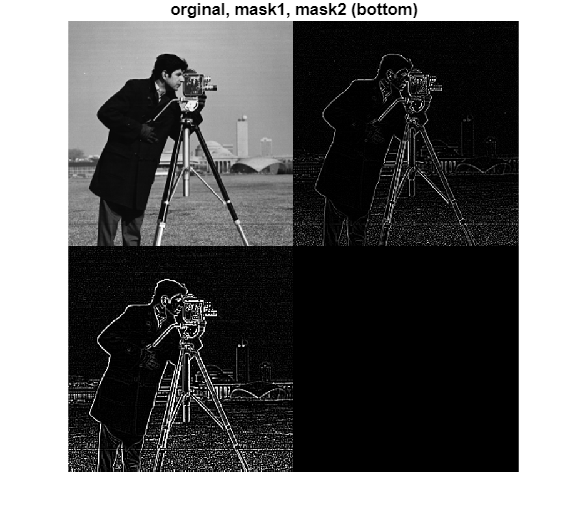

% 1. Mask filters
mask1_filter = [0 1 0; 1 -4 1; 0 1 0];
mask2_filter = [1 1 1; 1 -8 1; 1 1 1];
% 2. Apply the filters to images
cam_m1 = imfilter(cam, mask1_filter, "replicate");
cam_m2 = imfilter(cam, mask2_filter, "replicate");
noise2_m1 = imfilter(noise2, mask1_filter,"replicate");
noise2_m2 = imfilter(noise2, mask2_filter, "replicate");
% 3. Plot original and filtered images
% cameraman image
figure;
montage({cam, cam_m1, cam_m2})
title("orginal, mask1, mask2 (bottom)");

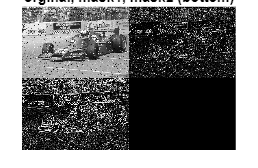

% noise2 image
figure;
montage({noise2, noise2_m1, noise2_m2});
title("orginal, mask1, mask2 (bottom)");

## Part 3: Gaussian Smoothing

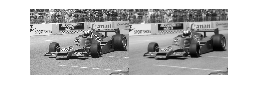

% a. Gaussian filter: 7x7, sigma = 1
gaus_f1 = fspecial("gaussian", 7, 1);
% Apply filter to the image
figure;
race_gf = imfilter(race, gaus_f1, "replicate");
imshowpair(race, race_gf, "montage");

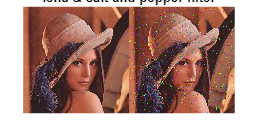

% b. Add salt and pepper noise to lena image 
lena_sp = imnoise(lena, "salt & pepper", 0.02);
figure;
imshowpair(lena, lena_sp, "montage");
title("lena & salt and pepper filter");

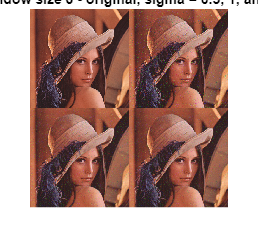

% c. Filter salt & pepper with different Gaussian combinations
% 1. Window size = 3 with 3 different sigma values 
gaus_fil305 = fspecial("gaussian", 3, 0.5);
gaus_fil31 = fspecial("gaussian", 3, 1);
gaus_fil32 = fspecial("gaussian", 3, 2);
% Apply filters to the image
lena_305 = imfilter(lena_sp, gaus_fil305, "replicate");
lena_31 = imfilter(lena_sp, gaus_fil31, "replicate");
lena_32 = imfilter(lena_sp, gaus_fil32, "replicate");
% Plot the original and filtered images
figure;
montage({lena, lena_305, lena_31, lena_32});
title("Window size 3 - original, sigma = 0.5, 1, and 2");

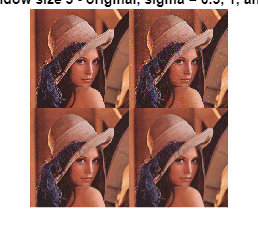

% 2. Window size = 5 with 3 different sigma values
gaus_fil505 = fspecial("gaussian", 5, 0.5);
gaus_fil51 = fspecial("gaussian", 5, 1);
gaus_fil52 = fspecial("gaussian", 5, 2);
% Apply filters to the image
lena_505 = imfilter(lena_sp, gaus_fil505, "replicate");
lena_51 = imfilter(lena_sp, gaus_fil51, "replicate");
lena_52 = imfilter(lena_sp, gaus_fil52, "replicate");
% Plot the original and filtered images
figure;
montage({lena, lena_505, lena_51, lena_52});
title("Window size 5 - original, sigma = 0.5, 1, and 2");

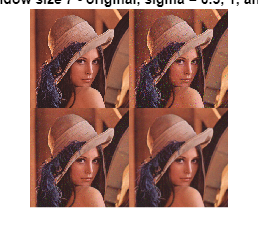

% 3. Window size = 7 with 3 different sigma values
gaus_fil705 = fspecial("gaussian", 7, 0.5);
gaus_fil71 = fspecial("gaussian", 7, 1);
gaus_fil72 = fspecial("gaussian", 7, 2);
% Apply filters to the image
lena_705 = imfilter(lena_sp, gaus_fil705, "replicate");
lena_71 = imfilter(lena_sp, gaus_fil71, "replicate");
lena_72 = imfilter(lena_sp, gaus_fil72, "replicate");
% Plot the original and filtered images
figure;
montage({lena, lena_705, lena_71, lena_72});
title("Window size 7 - original, sigma = 0.5, 1, and 2");

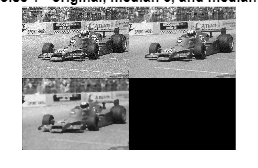

%% Part 4: Median Filtering
% 3x3 matrix
noise1_med3 = medfilt2(noise1, [3 3]);
noise2_med3 = medfilt2(noise2, [3 3]);
% 7x7 matrix
noise1_med7 = medfilt2(noise1, [7 7]);
noise2_med7 = medfilt2(noise2, [7 7]);
% Plot images
% Noise1 and its filtered images
figure;
montage({noise1, noise1_med3, noise1_med7});
title("Noise 1 - original, median 3, and median 7");

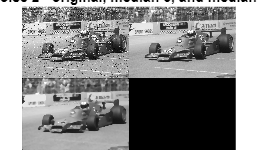

% Noise2 and its filtered images
figure;
montage({noise2, noise2_med3, noise2_med7});
title("Noise 2 - original, median 3, and median 7");

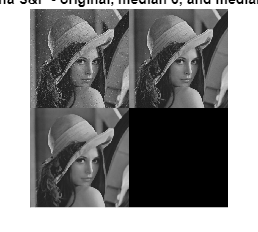

% Lena salt pepper grayscale convert
lena_spgray = rgb2gray(lena_sp);
% Apply filters on lena image
lena_med3 = medfilt2(lena_spgray, [3 3]);
lena_med7 = medfilt2(lena_spgray, [7 7]);
% Plot images
figure;
montage({lena_spgray, lena_med3, lena_med7});
title("Lena S&P - original, median 3, and median 7");